**Exercise 7**

Head Contours:

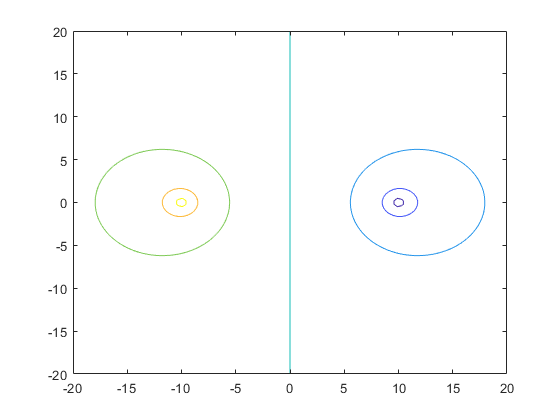

x = linspace(-20,20); % equally spaced vector n=100
y = linspace(-20,20);
[X,Y] = meshgrid(x,y); % creating meshgrid size(X and Y)=100 by 100
Z = h(X,Y);
contour(X,Y,Z)

Computing the velocity field given by Darcy’s law:

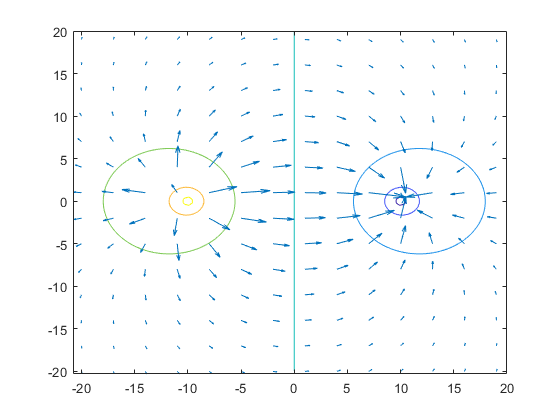

x = -20:3:20; % equally spaced vector n=100
y = x';
Z = h(x,y);
[px,py] = gradient(Z);
px = -px;
py = -py;
hold on;
quiver(x,y,px,py)
hold off

Equipotential lines ($\phi \left(x,y\right)$) and streamlines ($\psi \left(x,y\right)$):

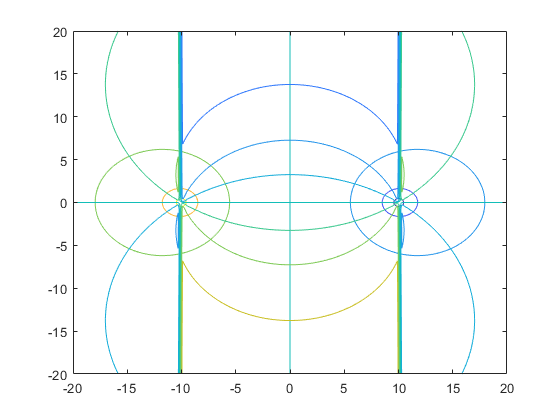


x = linspace(-20,20); % equally spaced vector n=100
y = linspace(-20,20);
[X,Y] = meshgrid(x,y);
z1 = phi(X,Y);
z2 = psi(X,Y);
hold on
contour(X,Y,z1)
contour(X,Y,z2)

function [h] = h(x,y)
a = 10; % meters
q = 100; % m^3/day
hw0 = 0; %initial uniform hydraulic head in the aquifer m
k = 1; % m/day
fraction = ((x-a).^2 + y.^2)./((x+a).^2 + y.^2);
h = hw0 + q/(4*pi*k)*log(fraction);
end

function [z] = phi(x,y) 
a = 10;
fraction = ((x-a).^2 + y.^2)./((x+a).^2 + y.^2);
q = 100; %m^3/day
z = q/(4*pi)*log(fraction);
end

function [z] = psi(x,y)
a = 10;
q = 100;
w = atan(y./(x-a)) - atan(y./(x+a));
z = q/(2*pi)*(w);
end

